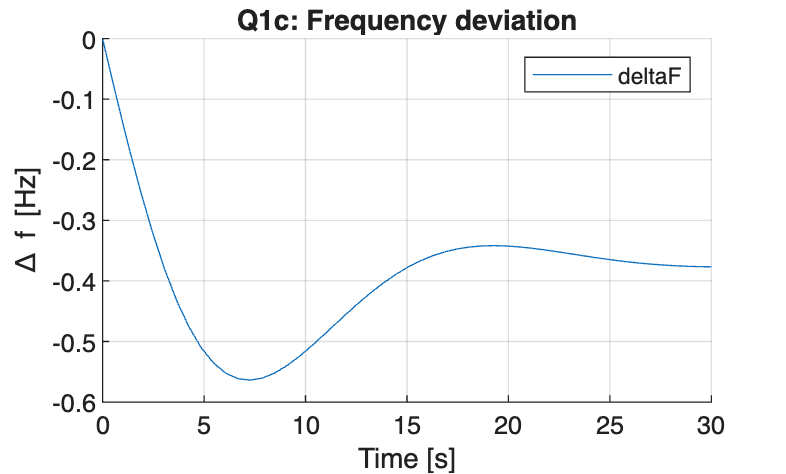

%% Q1
simuFile = 'q1cd';
load_system(simuFile);
set_param(simuFile, 'StopTime', '30');

simuResult = sim(simuFile); % run simulation

% q1c - angle

plot_scope(simuResult, {'deltaF'}, 'Time [s]', '\Delta f [Hz]', 'Q1c: Frequency deviation', 'part1c_freq.png');

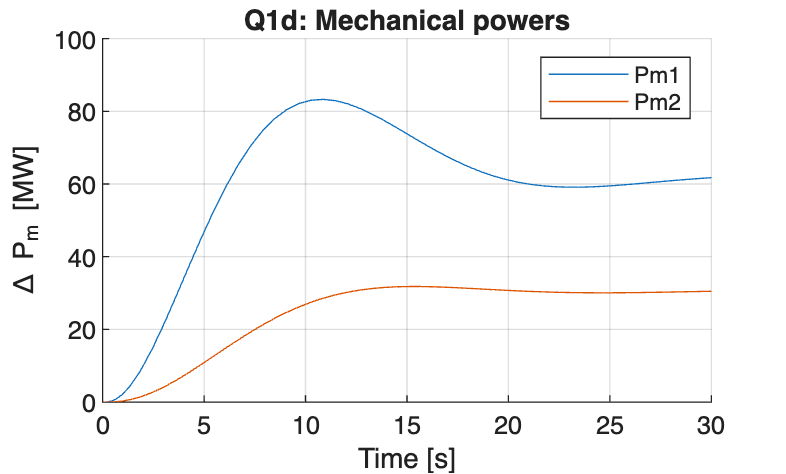


% q1d - Powers

plot_scope(simuResult, {'Pm1','Pm2'}, 'Time [s]', '\Delta P_m [MW]', 'Q1d: Mechanical powers', 'part1d_powers.png');

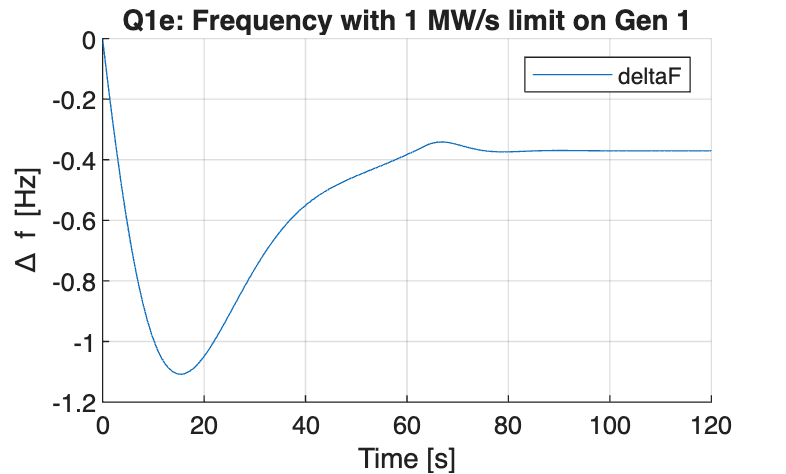


% q1e
simuFile = 'q1e';
load_system(simuFile);
set_param(simuFile, 'StopTime', '120');

simuResult = sim(simuFile); % Run simulation

% q1e plot requency
plot_scope(simuResult, {'deltaF'}, 'Time [s]', '\Delta f [Hz]', 'Q1e: Frequency with 1 MW/s limit on Gen 1', 'part1e_freq.png');

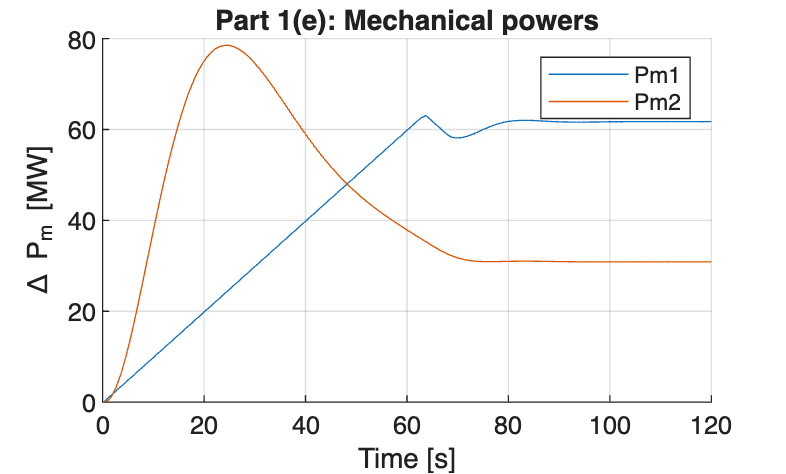


% q1e plot mechanical power
plot_scope(simuResult, {'Pm1','Pm2'}, 'Time [s]', '\Delta P_m [MW]', 'Part 1(e): Mechanical powers', 'part1e_powers.png');

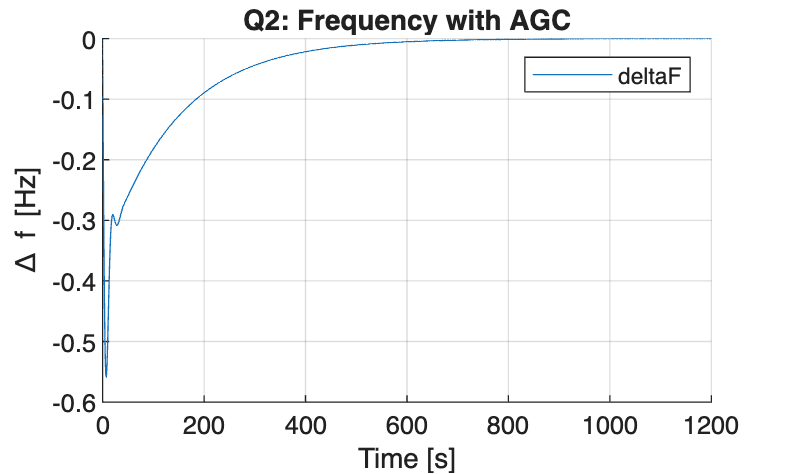


%% Q2

simuFile = 'q2';
load_system(simuFile);
set_param(simuFile, 'StopTime', '1200');

% run simulation
simuResult = sim(simuFile);

% plot frequency
plot_scope(simuResult, {'deltaF'}, 'Time [s]', '\Delta f [Hz]', 'Q2: Frequency with AGC', 'part2_freq.png');

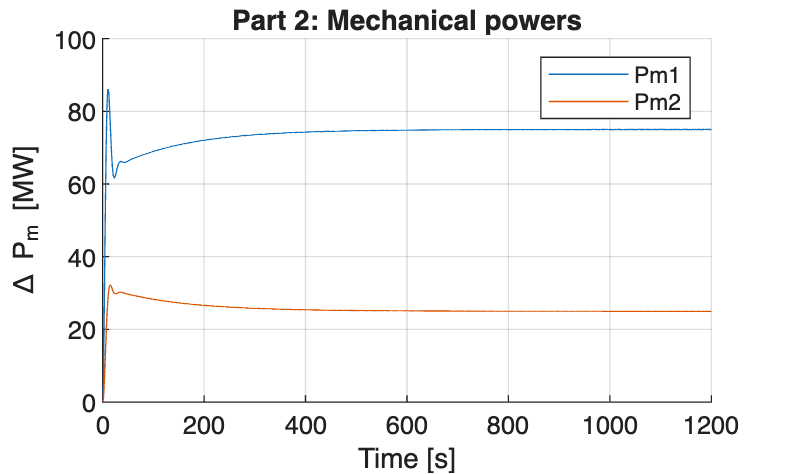


% plot mechanical powers
plot_scope(simuResult, {'Pm1','Pm2'}, 'Time [s]', '\Delta P_m [MW]', 'Part 2: Mechanical powers', 'part2_powers.png');

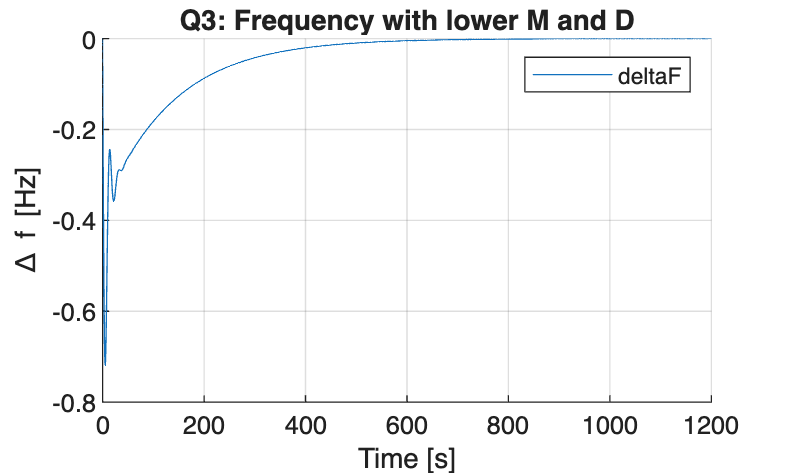


%% Q3
simuFile = 'q3';
load_system(simuFile);
set_param(simuFile, 'StopTime', '1200');

%Run simulation
simuResult = sim(simuFile);

% q3 plot requency
plot_scope(simuResult, {'deltaF'}, 'Time [s]', '\Delta f [Hz]', 'Q3: Frequency with lower M and D', 'part3_freq.png');

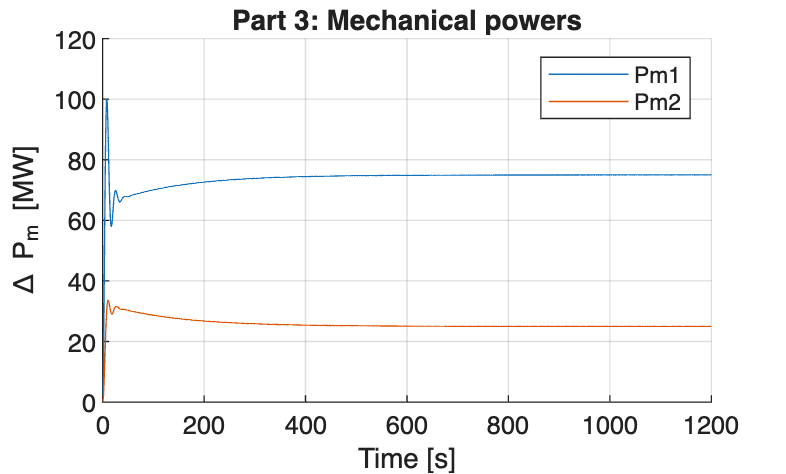


% q3 plot mechanical powers
plot_scope(simuResult, {'Pm1','Pm2'}, 'Time [s]', '\Delta P_m [MW]', 'Part 3: Mechanical powers', 'part3_powers.png');

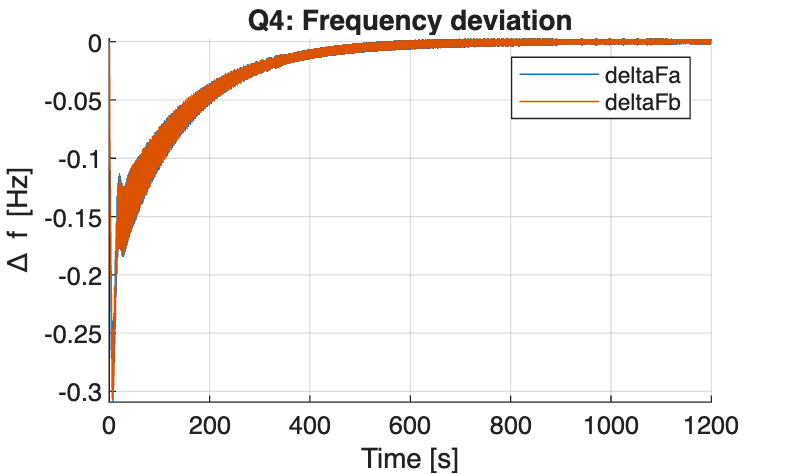


%% Q4 - No control
simuFile = 'q4_no_control';
load_system(simuFile);
set_param(simuFile, 'StopTime', '1200');

simuResult = sim(simuFile); % run simulation

% plot Frequency
plot_scope(simuResult, {'deltaFa', 'deltaFb'}, 'Time [s]', '\Delta f [Hz]', 'Q4: Frequency deviation', 'part4_freq.png');

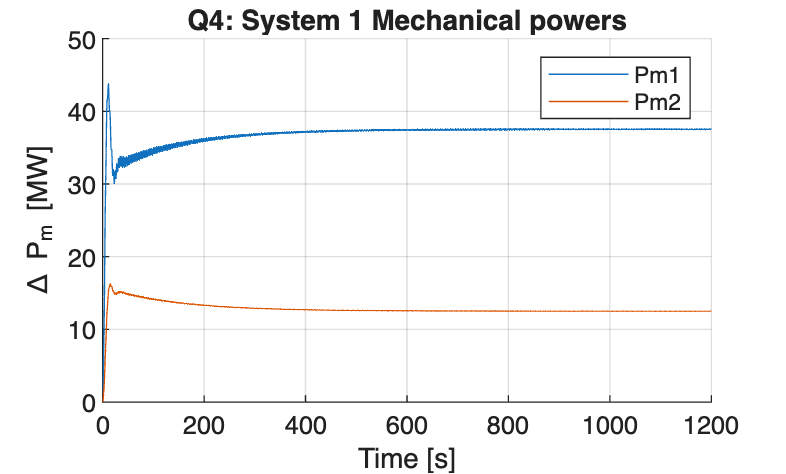


% plot System 1 Powers
plot_scope(simuResult, {'Pm1','Pm2'}, 'Time [s]', '\Delta P_m [MW]', 'Q4: System 1 Mechanical powers', 'part4_sys1_powers.png');

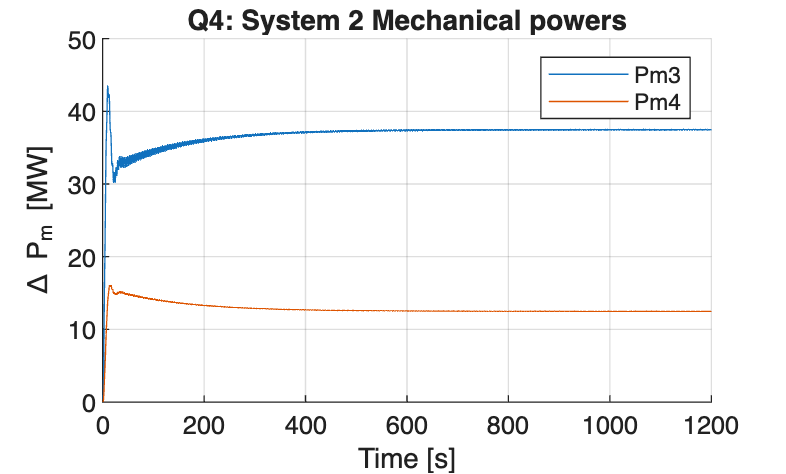


% plot system 2 Powers
plot_scope(simuResult, {'Pm3','Pm4'}, 'Time [s]', '\Delta P_m [MW]', 'Q4: System 2 Mechanical powers', 'part4_sys2_powers.png');

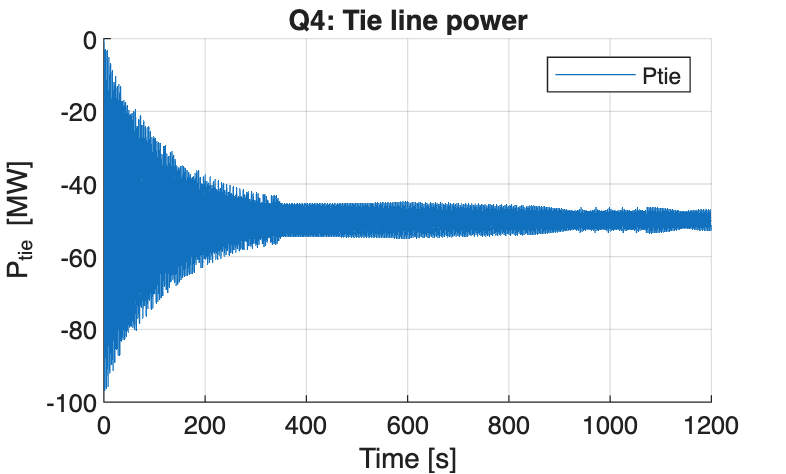


% plot tie Line Power
plot_scope(simuResult, {'Ptie'}, 'Time [s]', 'P_{tie} [MW]', 'Q4: Tie line power', 'part4_tieline.png');

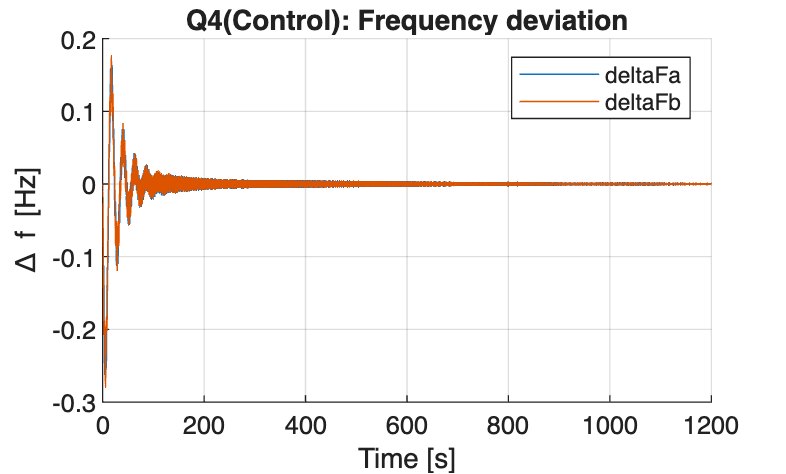


%% Q4 - With control
simuFile = 'q4_with_control';
load_system(simuFile);
set_param(simuFile, 'StopTime', '1200');

simuResult = sim(simuFile); % Run simulation

% plot Frequency
plot_scope(simuResult, {'deltaFa', 'deltaFb'}, 'Time [s]', '\Delta f [Hz]', 'Q4(Control): Frequency deviation', 'part4c_freq.png');

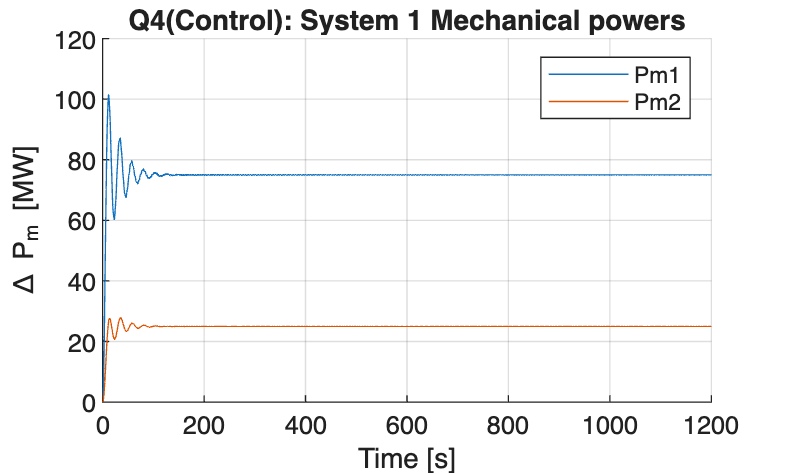


% plot System 1 Powers
plot_scope(simuResult, {'Pm1','Pm2'}, 'Time [s]', '\Delta P_m [MW]', 'Q4(Control): System 1 Mechanical powers', 'part4c_sys1_powers.png');

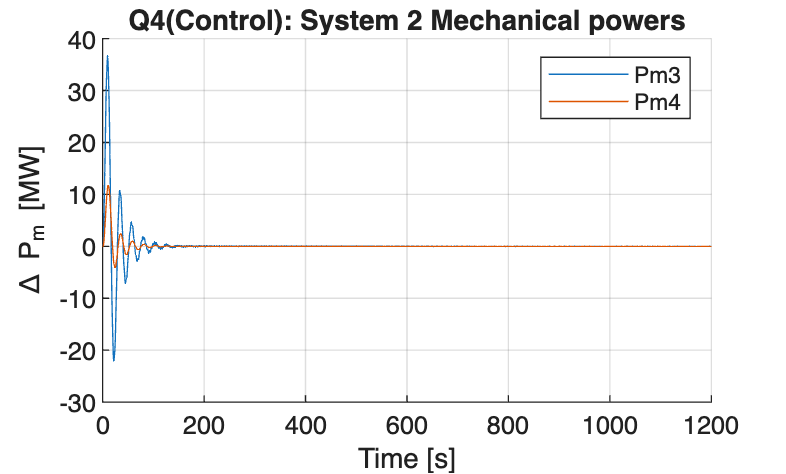


% plot system 2 Powers
plot_scope(simuResult, {'Pm3','Pm4'}, 'Time [s]', '\Delta P_m [MW]', 'Q4(Control): System 2 Mechanical powers', 'part4c_sys2_powers.png');

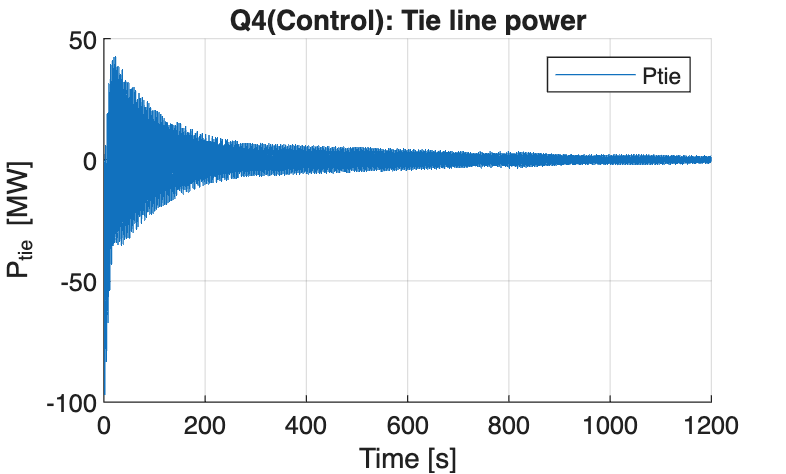


% plot tie Line Power
plot_scope(simuResult, {'Ptie'}, 'Time [s]', 'P_{tie} [MW]', 'Q4(Control): Tie line power', 'part4c_tieline.png');